# Statics: Forces in Equilibrium

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

In a variety of engineering disciplines and in physics, you may want to analyze static systems. This requires drawing a force diagram (vectors!) indicating all of the components that must balance to keep a static system from becoming a dynamic system. Adding up all of the vectors in the system must result in the zero vector in any static system. 

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## What is Statics?

To understand the state of any physical system, we use Newton's laws of motion. Informally, we can state the laws as follows:

- A force is required to change the motion of an object.

- Force = mass * acceleration

- When two objects interact, they exert equal and opposite forces on each other.

A static system is a system which is at rest. This means that all forces in the system must be exactly balanced by other forces in the system. Since we can represent forces as vectors, to study such systems we will draw a free-body diagram including the objects and forces in a system and use linear algebra to draw conclusions about the implications of Newton's laws on physical systems. 

## Decomposing Forces

Rather than adding up all the vectors at once, it is very common to consider a single direction at a time. This requires decomposing our forces into components in each direction. This can also allow us to move between different spatial representations such as cartesian, polar, or spherical. We will use unit vectors to track direction, and vector addition to combine each of the forces and identify the resultant force.

Consider the vector $\vec{A} = (A_x,A_y,A_z)$. It forms an angle of $\gamma$ with the $z$-axis, an angle of $\beta$ with the $y$-axis and an angle of $\alpha$ with the $x$-axis. 

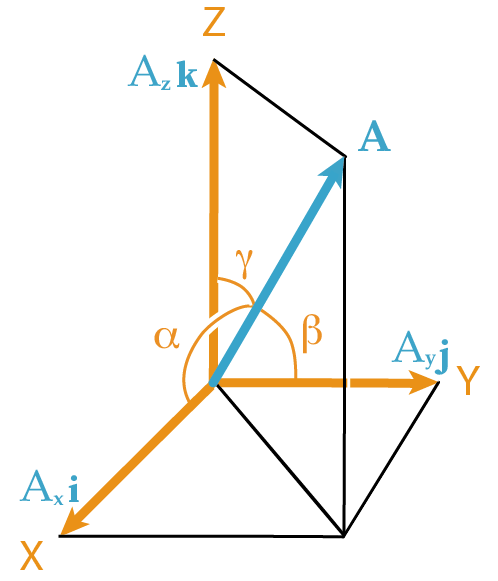

Let $\vec{u}_A$ be the unit vector in the direction of $\vec{A}$. 


$$\vec{A} = ||A||\cdot \vec{u_A}$$



$$\vec{u}_A = [u_x,u_y,u_z]$$



$$||\vec{u}_A|| = 1$$


The corresponding unit vector $u_A$ can be calculated by knowing two points along $A$,

$p_1 = (x_1, y_1, z_1)$ and  $p_2 = (x_2, y_2, z_2)$. The the distance between $p_1$ and $p_2$ is:


$$d=\sqrt{{\left(x_2 -x_1 \right)}^2 +{\left(y_2 -y_1 \right)}^2 +{\left(z_2 -z_1 \right)}^2 }$$
 
$$= ||p_2-p_1||$$


so the unit vector in the direction of $A$ is:

$u_A = \left[ \frac{x_2-x_1}{d},\frac{y_2-y_1}{d},\frac{z_2-z_1}{d}\right] = \frac{\vec{A}}{||A||} = \frac{p_2-p_1}{||p_2-p_1||}$.

In the case shown above, where the origin can be taken as $p_1$ and $(A_x,A_y,A_z)$ can be taken as $p_2$, 

$u_A = \left[\frac{A_x}{\sqrt{A_x^2+A_y^2+A_z^2}},\frac{A_y}{\sqrt{A_x^2+A_y^2+A_z^2}},\frac{A_z}{\sqrt{A_x^2+A_y^2+A_z^2}}\right]$.

## Compute the Magnitude and Direction of a Resultant Force

Determine the magnitude and direction of the resultant force on the hook at point $A$. 

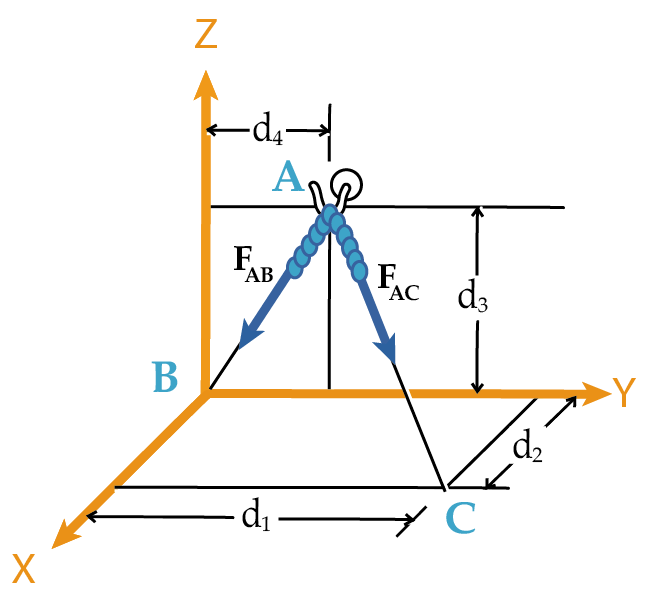

Say we know the measured distances: 

$d_1 = 8 \text{ m}$,      $d_2 = 4 \text{ m}$,      $d_3 = 4 \text{ m}$,      and      $d_4 = 2 \text{ m}$.

We can identify the points: 

$A = (0,2,4)$, $B = (0,0,0)$, and $C=(4,8,0)$. 

To work out the case of the force $F_{AB}$ by hand:

$\vec{AB} = B-A = (0,-2,-4)$ and $d_{AB} = \sqrt{0^2+(-2)^2+(-4)^2} = \sqrt{20}$.

Therefore,

$\vec{u_{AB}} = \frac{\vec{AB}}{d_{AB}} = \frac{\vec{AB}}{\left|\left|B-A\right|\right|}= \left(0,\frac{-2}{\sqrt{20}}, \frac{-4}{\sqrt{20}}\right)$,

and, if the magnitude of the force towards $B$ is $600$ Newtons:

$\vec{F_{AB}} = 600\cdot \vec{u_{AB}} = 600\left(0,\frac{-2}{\sqrt{20}}, \frac{-4}{\sqrt{20}}\right)$.

We could solve this question numerically as well:

% Define the points and forces of interest
A = [0 2 4];
B = [0 0 0];
C = [4 8 0];

% Identify the magnitudes of each force
F_AB = 600;
F_AC = 500;

% Decompose the force AB
AB = B-A;
u_AB = AB/norm(AB);
F_AB = u_AB*F_AB

% Decompose the force AC
AC = C-A;
u_AC = AC/norm(AC);
F_AC = u_AC*F_AC

% Calculate the resultant force
F_R = F_AB + F_AC

% Identify the direction of the resultant force
u_FR = F_R/norm(F_R)

  **Try**. 

- How does your resultant force change if you change the locations of $A$, $B$, and $C$? 

- How does your resultant force change if you change the magnitudes of the forces $F_{AB}$ and $F_{AC}$?

###  **Exercise 1: Calculate Forces in 3 Dimensions**

A trap door is held open by two chains, as depicted below. Express the given forces as cartesian vectors.

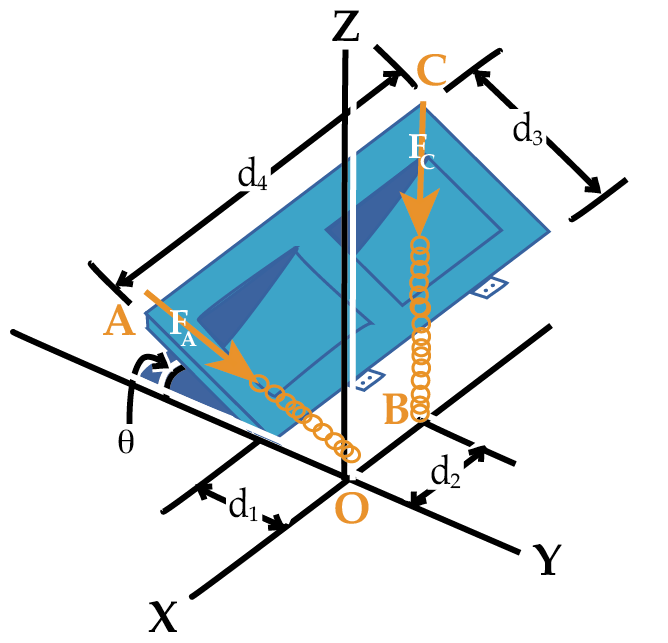

Choose values for the measurements in the diagram:

% Distances
d_1 = 3;   % meters
d_2 = 1.5; % meters
d_3 = 1; % meters
d_4 = 2.3; % meters

% Angle that the door makes with the floor 
theta = 30;  % degrees

% Magnitude of the forces
F_A = 300; % Newtons
F_C = 250; % Newtons

a) What are the coordinates of the point $B = (B_x,B_y,B_z)$ in terms of the measurements `d_1`, `d_2`, `d_3`, `d_4 `and `theta`?

flag = [0 0 0 0];
B_x =  NaN;
B_y =  NaN;
B_z =  NaN;
B = [B_x,B_y,B_z];
flag(1) = checkExercise1a(B,d_1,d_2,d_3,d_4,theta,F_A,F_C);  

b) What are the coordinates of the point $A = (A_x,A_y,A_z)$ in terms of the measurements `d_1`, `d_2`, `d_3`, `d_4 `and `theta`?

A_x =  NaN;
A_y =  NaN;
A_z =  NaN;
A = [A_x,A_y,A_z];
if ~exist("flag","var")
    flag = [-1 0 0 0];
end
flag(2) = checkExercise1b(A,d_1,d_2,d_3,d_4,theta,F_A,F_C);    

c) What are the coordinates of the point $ C = (C_x,C_y,C_z)$ in terms of the measurements `d_1`, `d_2`, `d_3`, `d_4 `and `theta`?

C_x =  NaN;
C_y =  NaN;
C_z =  NaN;
C = [C_x,C_y,C_z];    
if ~exist("flag","var")
    flag = [-1 -1 0 0];
end
flag(3) = checkExercise1c(C,d_1,d_2,d_3,d_4,theta,F_A,F_C);

F_AB =          0 -268.3282 -536.6563


d) What are the coordinates of the point $O = (O_x,O_y,O_z)$ in terms of the measurements `d_1`, `d_2`, `d_3`, `d_4 `and `theta`?

O_x =  NaN;
O_y =  NaN;
O_z =  NaN;
O = [O_x,O_y,O_z];
if ~exist("flag","var")

F_AC =   242.5356  363.8034 -242.5356


    flag = [-1 -1 -1 0];
end
flag(4) = checkExercise1d(O,d_1,d_2,d_3,d_4,theta,F_A,F_C);     

F_R =   242.5356   95.4753 -779.1919


e) What are the cartesian coordinates of the force vectors in Newtons in terms of `A`, `B`, `C`, and `O`?

F_A =  NaN;
F_C =  NaN;     
checkExercise1e(A,B,C,O,flag,1e-2,F_A,F_C);

u_FR =     0.2952    0.1162   -0.9483


 **Reflect**. Are there any forces missing from this diagram?

## Conditions of Equilibrium

There must be no displacement and no rotation. Mathematically, this is that the sum of all forces and the sum of all moments are both zero.

$\displaystyle \sum F = 0$      and      $\displaystyle \sum M = 0$.

###  **Exercise 2: Calculate Tensions in 3 Dimensions**

A box weighing 150 pounds, point E, is suspended below point A by three cables attached at points B, C, and D, as shown below. Determine the tension in each cable.

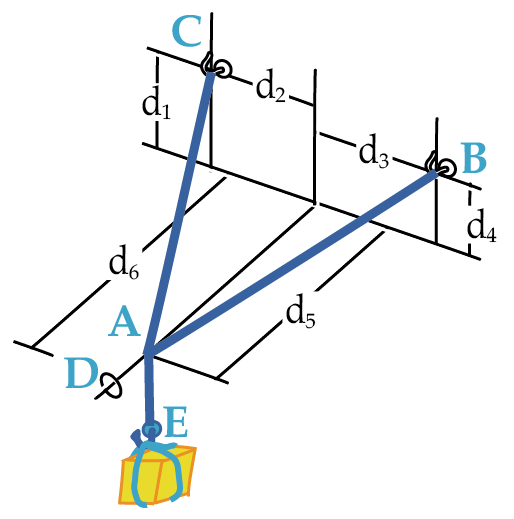

Assume the distances are measured as follows:

d_1 = 3; % feet
d_2 = 2; % feet
d_3 = 3; % feet
d_4 = 2; % feet
d_5 = 6; % feet
d_6 = 7; % feet

Define the weight of the box in pounds.

W =  nan;   

Identify the coordinates of the points A, B, C, and D in terms of the measured distances `d_1`, `d_2`, `d_3`, `d_4`, `d_5`, and `d_6`. Does it matter which point you choose to be the origin?

A = [0 0 0];   
B = [0 0 0];
C = [0 0 0];
D = [0 0 0 ];

Identify vectors along the relevant cables in terms of `A`, `B`, `C`, and `D`.

AB =  nan;
AC =  nan;
AD =  nan;

Normalize the vectors along the cables in terms of `A`, `B`, `C`, and `D`.

N_AB =  nan; 
N_AC =  nan;
N_AD =  nan;

Define symbolic variables representing the tension in each cable and a symbolic unit system.

syms F_AC F_AB F_AD
u = symunit;

Define a system of equations that balances the forces in each direction in terms of `F_AC`, `F_AB`, and `F_AD` as well as the normalized vectors and other forces in the problem. 

balance_x =  nan;
balance_y =  nan;
balance_z =  nan;

Solve the system of equations and display the results.

[F_AC, F_AB, F_AD]=solve([balance_x,balance_y,balance_z],[F_AC,F_AB,F_AD]);
outVal = checkEx2(F_AC,F_AB,F_AD,d_1,d_2,d_3,d_4,d_5,d_6,W);
if outVal
F_AC = round(F_AC,2)*u.lbf

The default value is nan. Please enter real numbers.


F_AB = round(F_AB,2)*u.lbf
F_AD = round(F_AD,2)*u.lbf
end

## References and Acknowledgements

Inspiration for this script came from work done by Professor [Orlando Arroyo](https://co.linkedin.com/in/orlando-arroyo-amell-9a68b151/en) of Universidad de La Sabana and conversations with Professor [Ricardo Parra Arango](https://co.linkedin.com/in/ricardo-l-parra-arango-661b0049). 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Helper Functions

function flag = givePtFeedback(myPt,corPt,ptName,ptAxis)
if isnan(myPt)
    disp("The default value is nan. Please enter real numbers.")
    flag = -1;
    return
end
if sign(myPt) ~= sign(corPt)

The default value is nan. Please enter real numbers.


    disp("Your value of " + ptName + " has the wrong sign.")
    disp("Which direction is the positive "+ ptAxis +" axis?")
    flag = 0;
elseif myPt ~= corPt
    disp("Your value of "+ ptName +" is incorrect.")
    disp("What is the displacement in the "+ ptAxis + " direction?")
    flag = 0;
else
    flag = 1;
end

The default value is nan. Please enter real numbers.


end

function flag = checkExercise1a(B,d_1,d_2,d_3,d_4,theta,F_A,F_C)
flag = givePtFeedback(B(1),-d_2,"B_x","x");
if flag == -1
    return
end

f = givePtFeedback(B(2),0,"B_y","y");
if f == -1

The default value is nan. Please enter real numbers.


    return
else
    flag = f*flag;
end
f = givePtFeedback(B(3),0,"B_z","z");

You must compute the correct cartesian coordinates for B, A, and C before continuing.


if f == -1
    return
else
    flag = f*flag;
end
if flag == 1
    disp("Correct. Please continue with the problem.")
end
end

function flag = checkExercise1b(D,d_1,d_2,d_3,d_4,theta,F_A,F_C)
Dx = D(1);
Dy = D(2);
Dz = D(3);
flag = givePtFeedback(Dx,0,"A_x","x");
if flag == -1
    return
end
f = givePtFeedback(Dy,-d_1-d_3*cosd(theta),"A_y","y");
if f == -1
    return
else
    if Dy == -d_1-d_3*cosd(theta)
        disp("What are the units of the argument to cos(theta) in MATLAB?")
        disp("Do you know the cosd() function?")
    elseif Dy == -d_1-d_3*sind(theta)
        disp("Do you want a sine or a cosine here?")
    end
    flag = f*flag;
end
f = givePtFeedback(Dz,d_3*sind(theta),"A_z","z");
if f == -1
    return
else
    if Dz == d_3*sind(theta)
        disp("What are the units of the argument to sin(theta) in MATLAB?")
        disp("Do you know the sind() function?")
    elseif Dz == d_3*cosd(theta)
        disp("Do you want a sine or a cosine here?")
    end
    flag = f*flag;
end

These are default values. Please complete the problem.


if flag == 1
    disp("Correct. Please continue with the problem.")
end
end

function flag = checkExercise1c(D,d_1,d_2,d_3,d_4,theta,F_A,F_C)
Dx = D(1);
Dy = D(2);
Dz = D(3);
flag = givePtFeedback(Dx,-d_4,"C_x","x");
if flag == -1
    return
end

f = givePtFeedback(Dy,-d_3*cosd(theta)-d_1,"C_y","y");
if f == -1
    return
else
    flag = f*flag;
end
f = givePtFeedback(Dz,d_3*sind(theta),"C_z","z");
if f == -1
    return
else
    flag = f*flag;
end
if flag == 1
    disp("Correct. Please continue with the problem.")
end
end

function flag = checkExercise1d(D,d_1,d_2,d_3,d_4,theta,F_A,F_C)
Dx = D(1);
Dy = D(2);
Dz = D(3);
flag = givePtFeedback(Dx,0,"O_x","x");
if flag == -1
    return
end

f = givePtFeedback(Dy,0,"O_y","y");
if f == -1
    return
else
    flag = f*flag;
end
f = givePtFeedback(Dz,0,"O_z","z");
if f == -1
    return
else
    flag = f*flag;
end
if flag == 1
    disp("Correct. Please continue with the problem.")
end
end

function checkExercise1e(A,B,C,D,flag,tol,FAB,FCD)
if any(flag~=1)
    opts = ["B" "A" "C" "O"];
    myOpts = opts(flag~=1);
    if length(myOpts) == 1
        myStr = myOpts;
    elseif length(myOpts) == 2
        myStr = myOpts(1) + " and " + myOpts(2);
    elseif length(myOpts) > 2
    myStr = sprintf("%s, ",myOpts(1:end-1)) + "and " + myOpts(end);
    else
        warning("How did you get here?")
    end
    disp("You must compute the correct cartesian coordinates for " + myStr + " before continuing.")
    return
end
uAB = (B-A)/norm(B-A);
uCD = (D-C)/norm(D-C);
forceAB = 300;
forceCD = 150;
if isnan(FAB)
    disp("This is the default value of F_A.")
    disp("Please calculate the cartesian coordinates of F_A.")
    return
else
    strFAB = sprintf("(%s,%s,%s)",string(FAB));
end
if all(FAB == forceAB*uAB) || norm(FAB-forceAB*uAB) < 6e-14
    disp("Yes, the cartesian force vector from A to O is " + strFAB )
elseif norm(FAB - forceAB*uAB)<tol
    disp("You are within tolerance for F_C, but could be more precise.")
    disp("Please don't round values until you must.")
else
    disp("Your cartesian force vector from A to O is incorrect.")
end
if isnan(FCD)
    disp("This is the default value of F_C.")
    disp("Please calculate the cartesian coordinates of F_C.")
    return
else
    strFCD = sprintf("(%s,%s,%s)",string(FCD));
end
if all(FCD == forceCD*uCD) || norm(FCD-forceCD*uCD) < 6e-14
     disp("Yes, the cartesian force vector from C to B is " + strFCD )
elseif norm(FCD - forceCD*uCD)<tol
    disp("You are within tolerance for F_C, but could be more precise.")
    disp("Please don't round values until you must.")
else
    disp("Your cartesian force vector from C to B is incorrect.")
end
end

function out = checkEx2(v1,v2,v3,d_1,d_2,d_3,d_4,d_5,d_6,W)
vecOut = [0 0 0];
if isempty(v1) || isempty(v2) || isempty(v3)
    disp("These are default values. Please complete the problem.")
    out = 0;
else
    [v1_sol,v2_sol,v3_sol] = SolveEx2(d_1,d_2,d_3,d_4,d_5,d_6,W);
if abs(double(v1) - double(v1_sol)) < 1e-2
    vecOut(1) = 1;
end
if abs(double(v2)-double(v2_sol)) < 1e-2
    vecOut(2) = 1;
end
if abs(double(v3)-double(v3_sol)) < 1e-2
    vecOut(3) = 1;
end
out = all(vecOut);
if out
    disp("That is correct.")
else
    optStr = ["FAC" "FAB" "FAD"];
    wrongSelect = optStr(vecOut);
    rightSelect = optStr(~vecOut);
    if length(wrongSelect) == 1
        disp(wrongSelect + " is incorrect but " + rightSelect(1) + " and " + rightSelect(2) + " are correct.")
    elseif length(wrongSelect) == 2
        disp(wrongSelect(1) + " and " + wrongSelect(2) + " are incorrect, but " + rightSelect + " is correct.")
    elseif length(wrongSelect) == 3
        disp("Your tension values are incorrect. Please check your work and try again.")
    else
        warning("How did you get here?")
    end
end
end
end

function [F_AC,F_AB,F_AD] = SolveEx2(d_1,d_2,d_3,d_4,d_5,d_6,W)
AB =  [d_5 d_3 d_4];
AC = [d_5 -d_2 d_1];
AD = [d_5-d_6 0 0];
N_AB = AB/norm(AB); 
N_AC = AC/norm(AC);
N_AD =  AD/norm(AD);
syms F_AC F_AB F_AD
balance_x = F_AB*N_AB(1)+F_AC*N_AC(1)+F_AD*N_AD(1) == 0;
balance_y = F_AB*N_AB(2)+F_AC*N_AC(2)+F_AD*N_AD(2) == 0;
balance_z = F_AB*N_AB(3)+F_AC*N_AC(3)+F_AD*N_AD(3) == W;
[F_AC, F_AB, F_AD]=solve([balance_x,balance_y,balance_z],[F_AC,F_AB,F_AD]);
end

% Allow the definition of apparently-unused variables because they will be
% required in the creation of student solutions.
%#ok<*NASGU>